## 等波纹法FIR滤波器设计

%% ===================== 参数定义 =====================
fs  = 32e6;            % 采样率 32 MHz
fp  = 2.5e6;           % 通带截止频率 2.5 MHz
fst = 4.0e6;           % 阻带起始频率 4.0 MHz
Ap  = 1;               % 通带最大衰减 1 dB
Ast = 50;              % 阻带最小衰减 50 dB

%% ===================== 允许偏差 (线性幅度偏差) =====================
dev = [ (10^(Ap/20)-1)/(10^(Ap/20)+1) , 10^(-Ast/20) ];

%% ===================== firpmord 估算阶数 =====================
[N, Fo, Ao, W] = firpmord([fp, fst], [1 0], dev, fs);
fprintf("firpmord 估算阶数 N = %d (taps=%d)\n", N, N+1);

firpmord 估算阶数 N = 36 (taps=37)



%% ===================== 方案B：自动加阶直到满足阻带 =====================
N0      = N + 1;       % 起点：你原来用的是 N+1
step    = 10;          % 每次加阶步长（可改 5/10/20）
maxIter = 40;          % 最大迭代次数
nFFT    = 16384;       % 频率采样点数（越大越准，但更慢）

best_b = [];
best_N = NaN;

for k = 0:maxIter
    Ntry = N0 + k*step;            % 试探阶数（firpm参数是“阶数”）
    b = firpm(Ntry, Fo, Ao, W);

    [H, F] = freqz(b, 1, nFFT, fs);
    HdB = 20*log10(abs(H) + 1e-12);

    passIdx = (F <= fp);
    stopIdx = (F >= fst);

    stopMax_dB = max(HdB(stopIdx));                       % 阻带最差点
    passRipple_pp = max(HdB(passIdx)) - min(HdB(passIdx));% 通带峰谷纹波

    fprintf("N=%4d (taps=%4d): stopMax=%7.2f dB, passRipple(pp)=%5.2f dB\n", ...
        Ntry, Ntry+1, stopMax_dB, passRipple_pp);

    if stopMax_dB <= -Ast
        best_b = b;
        best_N = Ntry;
        fprintf(">>> 满足阻带 Ast=%d dB：采用 N=%d (taps=%d)\n", Ast, best_N, best_N+1);
        break;
    end
end

N=  37 (taps=  38): stopMax= -47.47 dB, passRipple(pp)= 1.33 dB
N=  47 (taps=  48): stopMax= -54.72 dB, passRipple(pp)= 0.58 dB


>>> 满足阻带 Ast=50 dB：采用 N=47 (taps=48)


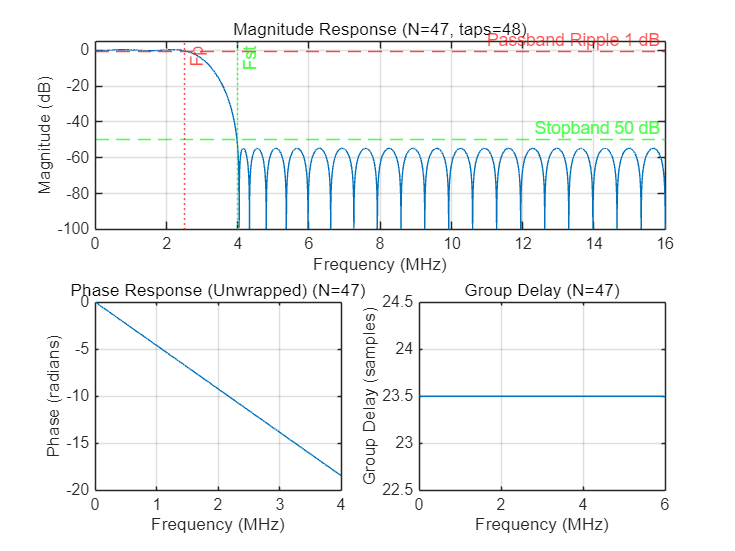


% 若没满足，也保留最后一次结果
if isempty(best_b)
    best_b = b;
    best_N = Ntry;
    fprintf("!!! 达到最大迭代仍未满足 Ast=%d dB，输出最后一次 N=%d (taps=%d)\n", Ast, best_N, best_N+1);
end

b = best_b;

%% ===================== 频率响应 & 群延迟 =====================
[H, F]   = freqz(b, 1, nFFT, fs);
[GD, Fg] = grpdelay(b, 1, nFFT, fs);
HdB = 20*log10(abs(H) + 1e-12);

%% ===================== 图1：幅频响应(dB) =====================
figure;
subplot(2,2,[1 2]);
plot(F/1e6, HdB); hold on;
yline(-Ap,  '--r', 'Passband Ripple 1 dB');
yline(-Ast, '--g', 'Stopband 50 dB');
xline(fp/1e6,  ':r', 'Fp');
xline(fst/1e6, ':g', 'Fst');
grid on; hold off;
xlabel('Frequency (MHz)'); ylabel('Magnitude (dB)');
title(sprintf('Magnitude Response (N=%d, taps=%d)', best_N, best_N+1));
ylim([-100 5]);

%% ===================== 图2：相频响应(解包裹) =====================
subplot(2,2,3);
plot(F/1e6, unwrap(angle(H)));
grid on;
xlabel('Frequency (MHz)'); ylabel('Phase (radians)');
title(sprintf('Phase Response (Unwrapped) (N=%d)', best_N));
xlim([0 4]);   % 你想看 0~4MHz 就改成 [0 4]

%% ===================== 图3：群延迟 =====================
subplot(2,2,4);
plot(Fg/1e6, GD);
grid on;
xlabel('Frequency (MHz)'); ylabel('Group Delay (samples)');
title(sprintf('Group Delay (N=%d)', best_N));
xlim([0 6]);   % 你想看 0~4MHz 就改成 [0 4]


%% ===================== 最终指标打印 =====================
passIdx = (F <= fp);
stopIdx = (F >= fst);
passRipple_pp = max(HdB(passIdx)) - min(HdB(passIdx));
stopMax_dB    = max(HdB(stopIdx));

fprintf("\n==== 最终结果 ====\n");


==== 最终结果 ====


fprintf("最终阶数 N = %d (taps=%d)\n", best_N, best_N+1);

最终阶数 N = 47 (taps=48)


fprintf("通带峰-谷纹波 = %.2f dB\n", passRipple_pp);

通带峰-谷纹波 = 0.58 dB


fprintf("阻带最差点 stopMax = %.2f dB (需 <= -%d dB)\n", stopMax_dB, Ast);

阻带最差点 stopMax = -54.72 dB (需 <= -50 dB)
